# vec(A) and reshape(A,p,q)

m = 3;
n = 4;
p = 4; 
q = 3; 
A = rand(m, n); % A is 3x4
B = reshape(A, p, q); % reshaping from 3x4 to 4x3

vec = reshape(A, [], 1); % This stacks the columns into a single column vector vec(A)


## Perfect Shuffle Permutation Matrix


input_vector = 1:12  % Vector to be shuffled

input_vector =      1     2     3     4     5     6     7     8     9    10    11    12


group_size = 4;      % Size of groups
shuffled_vector = perfect_shuffle(input_vector, group_size);
disp('Shuffled Vector:');

Shuffled Vector:


disp(shuffled_vector);

     1
     5
     9
     2
     6
    10
     3
     7
    11
     4
     8
    12



## Kronecker Product of 2 Matrices

r=2;
s=3;
p=4;
q=3;

A = randi(10,r,s)

A =      8     9     2
     1     3     2


B = randi(10,p,q)

B =     10     1     7
     9    10     2
     9     4     1
     5     6    10


C = kron(A,B)

C =     80     8    56    90     9    63    20     2    14
    72    80    16    81    90    18    18    20     4
    72    32     8    81    36     9    18     8     2
    40    48    80    45    54    90    10    12    20
    10     1     7    30     3    21    20     2    14
     9    10     2    27    30     6    18    20     4
     9     4     1    27    12     3    18     8     2
     5     6    10    15    18    30    10    12    20


## Hadamard Product

% H = B .* C                 % I should get an error (matrices are incompatible)
D = randi(10,3,4);
E = randi(10,3,4);
disp("Hadamard Product: ");

Hadamard Product: 


H = D .* E ;                 % this is correct



% Έλεγχος αν τα στοιχεία του Hadamard product είναι υποσύνολο του Kronecker product
disp("Kronecker Product: ");

Kronecker Product: 


F = kron(D,E);


isSubset = all(ismember(H(:), F(:)));
if isSubset
    disp('Are all elements of the Hadamard product a subset of the Kronecker product? true');
else
    disp('Are all elements of the Hadamard product a subset of the Kronecker product? false');
end

Are all elements of the Hadamard product a subset of the Kronecker product? true


## Timeit Function


% Παράδειγμα 1: Απλή Συνάρτηση
myFun = @() eig(rand(100));
elapsedTime = timeit(myFun);
disp(elapsedTime);


% Παράδειγμα 2: Συνάρτηση με Ορίσματα
x = rand(1,1000);
myFun = @() sort(x);
elapsedTime = timeit(myFun);
disp(elapsedTime);



% ορθή χρήση
n=1000;
A=randn(n); B=randn(n); u=randn(n,1); v=randn(n,1);
fn_ger=@()A+B*(u*v');
timeit(fn_ger)


%
n = 100;
A=randn(n); B=randn(n); u=randn(n,1); v=randn(n,1);
fn_ger=@(A,B,u,v)A+B*(u*v');
try
 timeit(fn_ger) %Αστοχία!
catch
 warning('Δεν επιτρέπεται η κλήση συναρτήσεων με παραμέτρους εισόδου.');
end


%timeit(fn_ger) %Αστοχία!

n=100;
A=randn(n);B=randn(n);u=randn(n,1);v=randn(n,1);
fn_ger=@()A+B*(u*v');
t(1)=timeit(fn_ger)

n=800;
A=randn(n);B=randn(n);u=randn(n,1);v=randn(n,1);
t(2)=timeit(fn_ger)

% παρατηρήστε ότι t(1) είναι περίπου ίσο με το t(2) !!!
% η 2η μέτρηση είναι λανθασμένη - πρέπει να οριστεί εκ νέου η fn_ger
% ορθή χρήση, δοκιμάζουμε διαστάσεις n = 100*2.^[0:kmax]
kmax = 5;
n = 100*2.^[0:kmax]

for j=0:kmax
 A=randn(n(j+1));B=randn(n(j+1));u=randn(n(j+1),1);
 v=randn(n(j+1),1);
 fn_ger=@()A+B*(u*v');
 t(j+1)=timeit(fn_ger); % για να αποφευχθεί μηδενικός δείκτης
end

% επιβράδυνση λόγω του διπλασιασμού του n
d=t(2:end)./t(1:end-1); disp(d')


% -------------------------------------------------------------
clear;
clc;
kmax = 6;
n = 100*2.^[0:kmax]

for j=0:kmax
 A=randn(n(j+1));B=randn(n(j+1));u=randn(n(j+1),1);
 v=randn(n(j+1),1);
 fn_ger=@()A+(B*u)*v';
 t(j+1)=timeit(fn_ger) ; % για να αποφευχθεί μηδενικός δείκτης
end
% επιβράδυνση λόγω του διπλασιασμού του n
d=t(2:end)./t(1:end-1); disp(d')

%--------------------------------------------------------------------


% εκδοχή με άμεση εισαγωγή της διάστασης από τον χρήστη
% εκδοχή με άμεση εισαγωγή της διάστασης από τον χρήστη
clear; clc;
n(1)=NaN; cnt=0;
while (n(end)~=0)
 cnt=cnt+1;
 n(cnt)=input('Enter dimension: ');
 A=randn(n(cnt));B=randn(n(cnt));u=randn(n(cnt),1);v=randn(n(cnt),1);
 fn_ger=@()A+B*(u*v');
 t(cnt)=timeit(fn_ger);
end
fprintf('%6s\t%10s\n', 'Index', 'Time (sec)');

 Index	Time (sec)


fprintf('%6d\t%10.4f\n', [ n(1:length(n)-1)' t(1:length(n)-1)']');

   200	    0.0016
   400	    0.0119
   600	    0.0342
   800	    0.0576
  1000	    0.1113
  1200	    0.2282
  1400	    0.3038
  1600	    0.5246


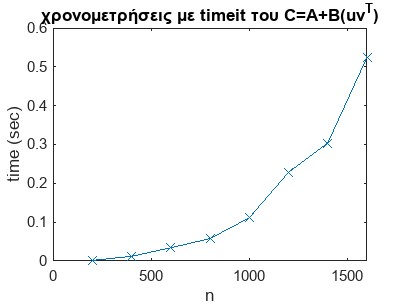


plot(n(1:end-1),t(1:end-1),'-x');
xlabel('n'); ylabel('time (sec)'); title('χρονομετρήσεις με timeit του C=A+B(uv^T)')


% :-)

function shuffled_vector = perfect_shuffle(input_vector, group_size)
    % Input:
    % input_vector: A vector of elements to be shuffled.
    % group_size: The size of the groups to split the input vector.

    n = length(input_vector);
    

    % Number of groups
    num_groups = n / group_size;
    
    % Create the identity matrix
    identity_matrix = eye(n);
    
    % Create a modified permutation matrix
    Pq_r = identity_matrix([(1 : group_size : n), (2 : group_size : n), (3 : group_size : n), (group_size:group_size:n)], :);
    
    % Create the shuffled vector by multiplying the permutation matrix with the input vector
    shuffled_vector = Pq_r * input_vector';
end


